# Analysis 1

## Load data

cd('F:\Data\C-Cdt1\C195-IF-total')

dataDir = 'F:\Data\C-Cdt1\C195-IF-total\Data\';
imagePath = '';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%rows = [4 5];
conditions = {
    'DMSO 35',[1:4],3:5,1:37,'DMSO','35'; 
    'DMSO 36',[5:8],3:5,1:37,'DMSO','36'; 
    
    'DAB post 35',[1:4],6:8,1:37,'DAB post','35'; 
    'DAB post 36',[5:8],6:8,1:37,'DAB post','36';  
    
    'DAB pre 35',[1:4],9:11,1:37,'DAB pre','35'; 
    'DAB pre 36',[5:8],9:11,1:37,'DAB pre','36';  
    
    'unreleased 35',[1:4],2,1:37,'unreleased','35'; 
    'unreleased 36',[5:8],2,1:37,'unreleased','36';  
    
    'NR dox',[1:4],12,1:37,'NR','35'; 
    'R no dox',[5:8],12,1:37,'R','36'; 
    };

S = loadData_IF(conditions, dataDir);


**Single scatter plot gated**

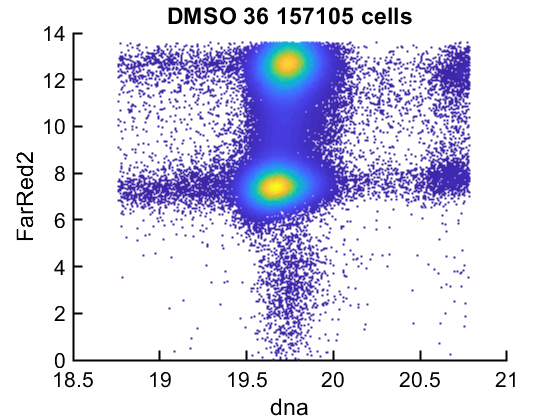

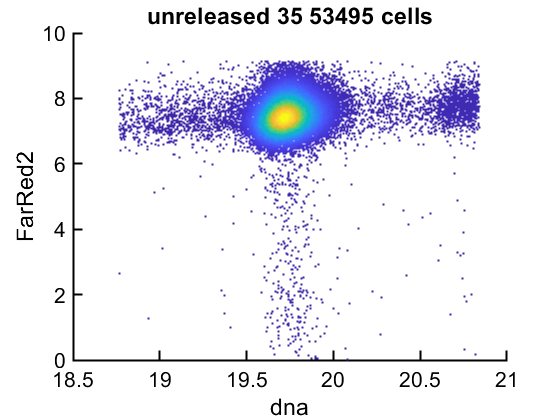

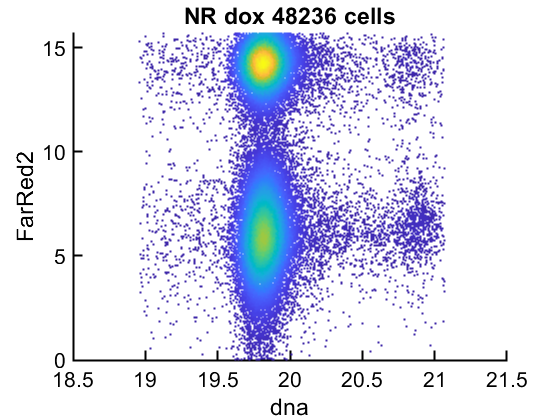

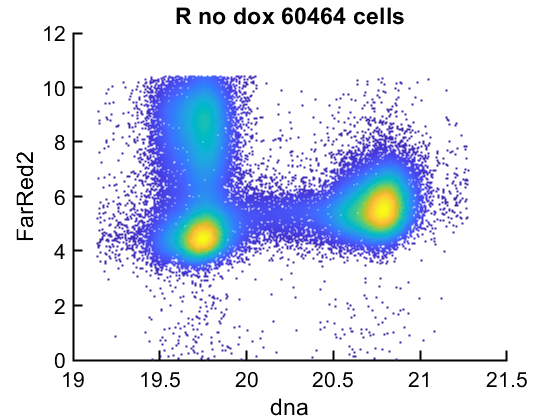

conds = [2 7 9 10];

xval = 'dna';
%xbg = [xval 'bg'];
yval = 'FarRed2';
%ybg = [yval 'bg'];

gateVals = {};
rangeVals = {[2^6 2^14]}; 


for i = 1:length(conds)
    condition = conds(i);
    xdata = log2(S(condition).(xval));
    ydata =  log2(S(condition).(yval));
    
    totalGate = true(size(xdata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    xdata = xdata(totalGate);
    ydata = ydata(totalGate);
    %downsample = 5000;
    xmin = prctile(xdata,.5); xmax = prctile(xdata,99.5);
    ymin = prctile(ydata,.5); ymax = prctile(ydata,99.5);
    ind = xdata>xmin & xdata<xmax & ydata>ymin & ydata<ymax;
%     %ind = randsample(length(xdata),downsample);
     xdata = xdata(ind); ydata = ydata(ind);
%     
    figure,
    dscatter(xdata,ydata);
    ylabel(yval);xlabel(xval);
%     xlim([2 10]); 
%     ylim([4 12]);
   title([conditions{condition,1} ' ' num2str(length(xdata)) ' cells'])

    
end

**Single scatter plot gated**

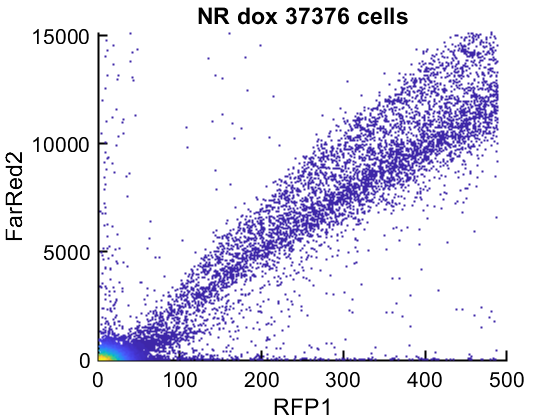

conds = [9];

xval = 'RFP1';
%xbg = [xval 'bg'];
yval = 'FarRed2';
%ybg = [yval 'bg'];

gateVals = {'RFP1'};
rangeVals = {[0 500]}; 


for i = 1:length(conds)
    condition = conds(i);
    xdata = (S(condition).(xval));
    ydata =  (S(condition).(yval));
    
    totalGate = true(size(xdata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    xdata = xdata(totalGate);
    ydata = ydata(totalGate);
    %downsample = 5000;
    xmin = prctile(xdata,.5); xmax = prctile(xdata,99.5);
    ymin = prctile(ydata,.5); ymax = prctile(ydata,99.5);
    ind = xdata>xmin & xdata<xmax & ydata>ymin & ydata<ymax;
%     %ind = randsample(length(xdata),downsample);
     xdata = xdata(ind); ydata = ydata(ind);
%     
    figure,
    dscatter(xdata,ydata);
    ylabel(yval);xlabel(xval);
%     xlim([2 10]); 
%     ylim([4 12]);
   title([conditions{condition,1} ' ' num2str(length(xdata)) ' cells'])

    
end

**Compare histograms of gem-venus**

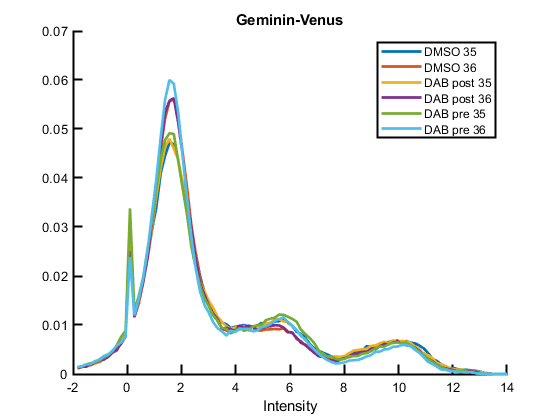

conds = [1 2 3 4 5 6];

yval = 'YFP1';

gateVals = {};
rangeVals = {[2^7 2^11]}; 

figure, hold on
for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    edges = linspace(-2,14,100);
    
    [N,~] = histcounts(ydata,edges);
    plot(edges(2:end),N/length(ydata),'Linewidth',2);
end
xlabel('Intensity')
title('Geminin-Venus')
legend(conditions(conds,1));

hold off

**Compare histograms of mCherry**

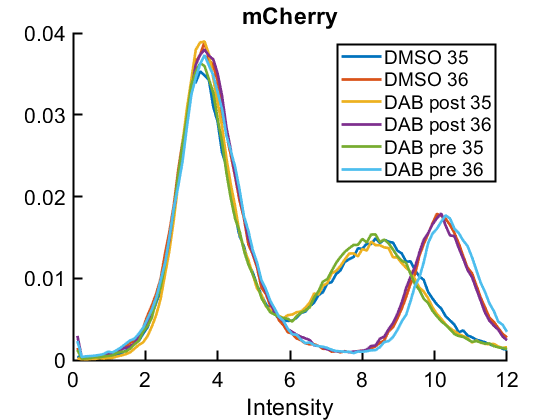

conds = [1 2 3 4 5 6];

yval = 'RFP1';

gateVals = {};
rangeVals = {[2^7 2^11]}; 

figure, hold on
for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    edges = linspace(0,12,100);
    
    [N,~] = histcounts(ydata,edges);
    plot(edges(2:end),N/length(ydata),'Linewidth',2);
end
legend(conditions(conds,1));
xlabel('Intensity')
hold off
title('mCherry')
set(gca,'FontSize',16)

**Compare histograms of EdU no gate**

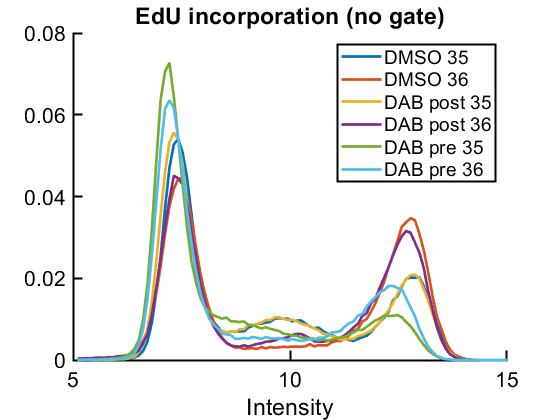

conds = [1 2 3 4 5 6];

yval = 'FarRed2';

gateVals = {};
rangeVals = {[2^5 2^11]}; 

figure, hold on
for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    edges = linspace(5,15,100);
    
    [N,~] = histcounts(ydata,edges);
    plot(edges(2:end),N/length(ydata),'Linewidth',2);
end
legend(conditions(conds,1));
xlabel('Intensity')
hold off
title('EdU incorporation (no gate)')
set(gca,'FontSize',16)

**Compare histograms of EdU APC off**

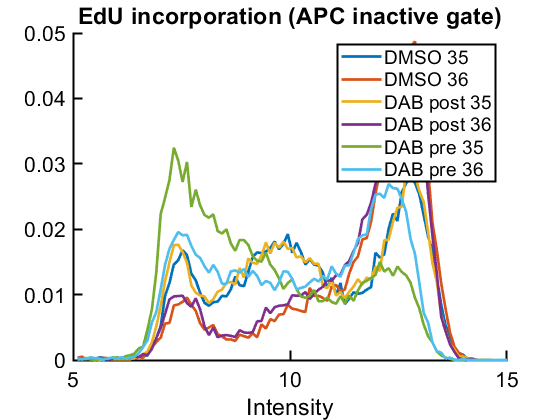

conds = [1 2 3 4 5 6];

yval = 'FarRed2';

gateVals = {'YFP1'};
rangeVals = {[2^8 2^20]}; 

figure, hold on
for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    edges = linspace(5,15,100);
    
    [N,~] = histcounts(ydata,edges);
    plot(edges(2:end),N/length(ydata),'Linewidth',2);
end
legend(conditions(conds,1));
xlabel('Intensity')
hold off
title('EdU incorporation (APC inactive gate)')
set(gca,'FontSize',16)

**Compare histograms of EdU APC off mCherry positive**

conds = [1 2 3 4 5 6];

yval = 'FarRed2';

gateVals = {'YFP1','RFP1'};
rangeVals = {[2^8 2^20],[2^8 2^20]}; 

figure, hold on
for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    edges = linspace(5,15,50);
    
    [N,~] = histcounts(ydata,edges);
    plot(edges(2:end),N/length(ydata),'Linewidth',2);
    length(ydata)
end

ans = 6701

ans = 6541

ans = 5872

ans = 6273

ans = 5369

ans = 5249

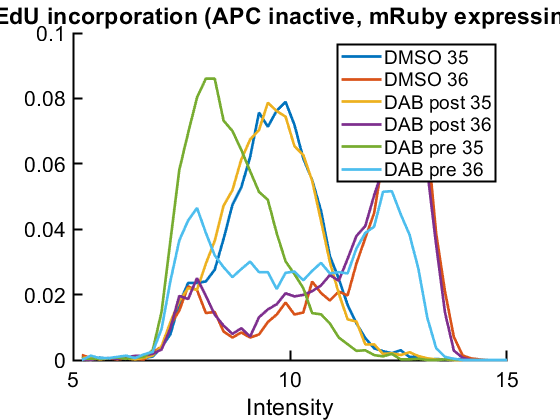

legend(conditions(conds,1));                          
xlabel('Intensity')
hold off
title('EdU incorporation (APC inactive, mRuby expressing)')
set(gca,'FontSize',16)

**Compare histograms of EdU APC off mRuby negative**

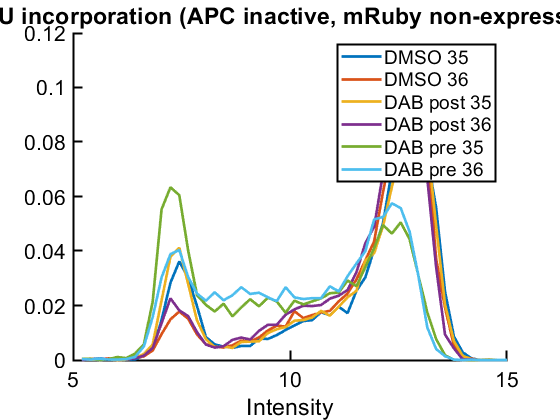

conds = [1 2 3 4 5 6];

yval = 'FarRed2';

gateVals = {'YFP1','RFP1'};
rangeVals = {[2^8 2^20],[2^0 2^5]}; 

figure, hold on
for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    edges = linspace(5,15,50);
    
    [N,~] = histcounts(ydata,edges);
    plot(edges(2:end),N/length(ydata),'Linewidth',2);
end
legend(conditions(conds,1));
xlabel('Intensity')
hold off
title('EdU incorporation (APC inactive, mRuby non-expressing)')
set(gca,'FontSize',16)

**Load data into table**

conds=1:8;

dfTotal = table();

apclims = [2^8 2^20];
gateVals = {{'YFP1'},{'YFP1'},{'YFP1'},{'YFP1'},{'YFP1'},{'YFP1'},{'YFP1'},{'YFP1'}};
rangeVals = {{apclims},{apclims},{apclims},{apclims},{apclims},{apclims},{apclims},{apclims}};

for i=1:length(conds)
    ind = true(size(S(conds(i)).area));
    apc=S(conds(i)).YFP1(ind);
    edu=S(conds(i)).FarRed2(ind);
    sig=S(conds(i)).RFP1(ind);
    dna = S(conds(i)).dna(ind);
    
    gates = gateVals{i};
    for j=1:length(gates)
        gateData = S(conds(i)).(gates{j})(ind);
        %gateData = S(conds(i)).(gates{j})(ind,end);
        inds = gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);
        apc = apc(inds);
        edu = edu(inds);
        sig = sig(inds);
        dna = dna(inds);
    end
    
    apc(apc<0.01) = 0.01;
    edu(edu<0.01) = 0.01;
    sig(sig<0.01) = 0.01;

    drugTreatment = repmat(categorical(conditions(conds(i),5)),numel(apc),1);
    constTreatment = repmat(categorical(conditions(conds(i),6)),numel(apc),1);
    
    dfTotal = [dfTotal;table(drugTreatment, constTreatment,apc,edu,sig)];
end

dfTotal.condition = categorical(strcat(string(dfTotal.constTreatment),{'\'},string(dfTotal.drugTreatment)));
dfTotal = movevars(dfTotal,'condition','After','constTreatment');
rubyEdges = [2^0 2^5 2^9 2^12];
dfTotal.rubyLevel = discretize(dfTotal.sig,rubyEdges,'categorical',{'no','low','high'});
%dfTotal = dfTotal(dfTotal.rubyLevel == 'no' | dfTotal.rubyLevel == 'high',:);
%dfTotal = dfTotal( dfTotal.rubyLevel == 'high',:);

% [G,names]  = findgroups(dfTotal.condition);
% index = [];
% subnumber = [445 376 401 500 500 500];
% for i = 1:max(G)
%     catInd = find(G==i);
%     subCat = datasample(catInd,subnumber(i),'Replace',false);
%     index = [index;subCat];
% end
% index = sort(index);
% dfTotal = dfTotal(index,:);


g = gramm('x',dfTotal.condition,'y',log2(dfTotal.edu),'subset',dfTotal.rubyLevel == 'high' & dfTotal.drugTreatment ~= 'unreleased');
g.set_order_options('x',{'36\DMSO','36\DAB post','36\DAB pre','35\DMSO','35\DAB post','35\DAB pre'});
g.set_names('x','','y','EdU intensity (AU)');
g.stat_boxplot('notch',1);
%g.stat_summary('geom',{'black_errorbar'},'type','ci');
%g.geom_jitter();
%g.stat_violin('normalization','width');
g.axe_property('XTickLabelRotation',45,'FontSize',16);
g.set_color_options('map','matlab');
g.geom_hline('yintercept',mean(log2(dfTotal.edu(dfTotal.drugTreatment == 'unreleased' & dfTotal.rubyLevel == 'high' & dfTotal.constTreatment == '35'))));
figure,
g.draw();

ordering given as values


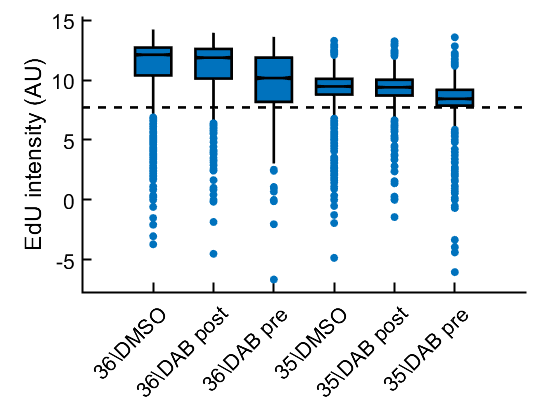

set(findall(gcf, 'Type', 'Patch'),'LineWidth',2);
set(findall(gcf, 'Type', 'Line'),'LineWidth',2);

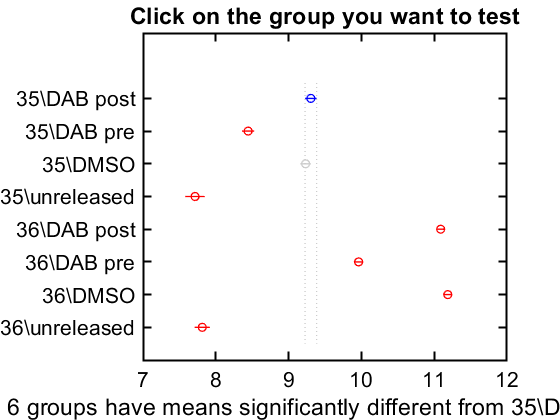


figure
inds = dfTotal.rubyLevel == 'high';
 [~,~,stats] = anova1(log2(dfTotal.edu(inds)),dfTotal.condition(inds),'off');
eduPostHoc = multcompare(stats);

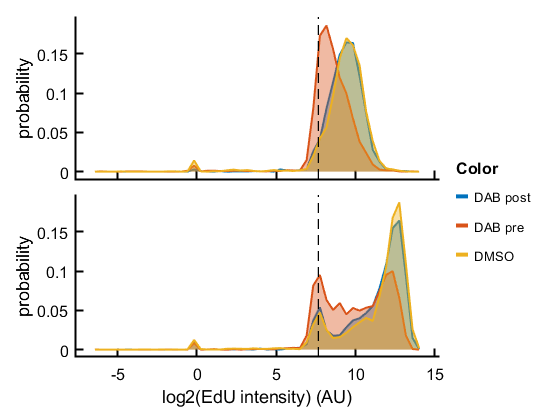

g = gramm('x',log2(dfTotal.edu),'color',dfTotal.drugTreatment,...%,'linestyle',dfTotal.drugTreatment,...
    'subset',dfTotal.drugTreatment ~= 'unreleased' & dfTotal.rubyLevel == 'high');
%g.set_order_options('color',{'NR56','NR28'});
g.facet_grid(dfTotal.constTreatment,[],'row_labels',false);
g.set_names('x','log2(EdU intensity) (AU)');
g.stat_bin('geom','line','normalization','probability','fill','transparent','nbins',50);
g.axe_property('FontSize',12);
g.set_color_options('map','matlab');
g.geom_vline('xintercept',mean(log2(dfTotal.edu(dfTotal.drugTreatment == 'unreleased'))));
figure,
g.draw();

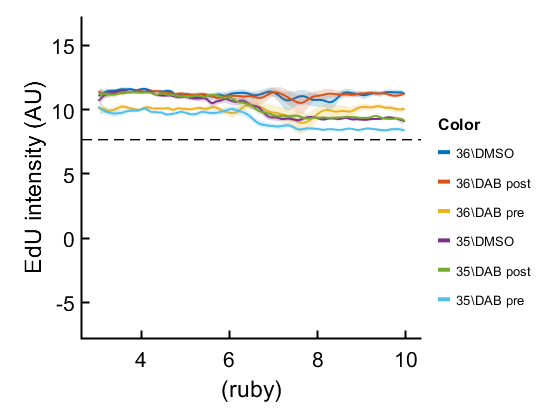

ordering given as values


g = gramm('x',log2(dfTotal.sig),'y',log2(dfTotal.edu),'color',dfTotal.condition,...
    'subset',dfTotal.drugTreatment ~='unreleased' & dfTotal.sig < 2^10 & dfTotal.sig > 2^3);
g.set_order_options('color',{'36\DMSO','36\DAB post','36\DAB pre','35\DMSO','35\DAB post','35\DAB pre'});
g.set_names('x','(ruby)','y','EdU intensity (AU)');
%g.geom_point();
%g.stat_summary('bin_in',10);
g.stat_smooth();
g.set_color_options('map','matlab');
g.axe_property('FontSize',16);
g.geom_hline('yintercept',mean(log2(dfTotal.edu(dfTotal.drugTreatment == 'unreleased'))));
figure,
g.draw();

figure



% impth = 'D:\4TB2\Data\C115-IF-ICE\Raw\';
% test = S(3);
% xdata = log2(test.FITC);
% ydata = log2(test.FarRed);
% 
% inds = test.dna < 2^22.5;
% xdata = xdata(inds);
% ydata = ydata(inds);
% 
% 
% cellviewer(xdata,ydata,test.shot(inds),[test.pos(inds,:)],'FITC','FarRed',impth);